# Instituto Tecnológico de Aeronaútica

### Aluno: Eduardo Bezerra Robalinho Dantas da Gama;

### Professor: Dr. Francisco Alex Correia Monteiro

Problema da curva:

n=1000;
x=rand_ger(n,0,1);

Seq =     0.0000    0.0314    0.8610    0.2340    0.0671    0.6027    0.2574    0.0367    0.5882    0.2449    0.1513    0.4218    0.5913    0.1488    0.6117    0.9282    0.6462    0.5379    0.6310    0.8936    0.3166    0.6065    0.0555    0.9235    0.5044    0.2382    0.1783    0.8594    0.2928    0.2249    0.8339    0.2481    0.2907    0.9854    0.9913    0.3103    0.4760    0.7842    0.8483    0.4090    0.5394    0.4503    0.4246    0.0188    0.7284    0.5960    0.6563    0.1942    0.1908    0.3353


Função desigualdade

f=@(x) 40*x.^2+7-43*x;

Vetor para receber o resultado das operações:

y=zeros(n,1);
y(:,1)=f(x(:,1));

Análisar ver se os valores estão dentro do intervalo  trabalhado:

prop=0;
for i=1:n
    if y(i,1)>0
        prop=prop+1;
    end
end
prop=prop/n

prop = 0.3250

Print dos gráficos:

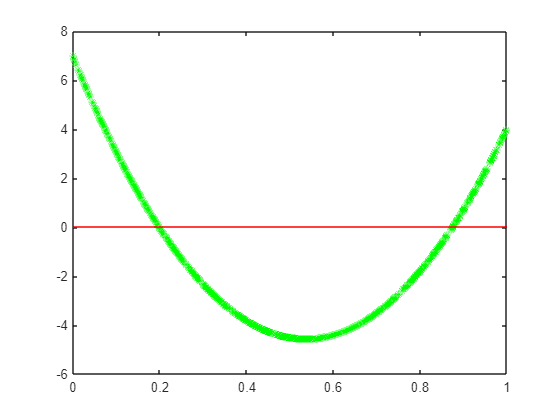

plot(x,y,'g*');
hold on
plot(x,zeros(n,1),'red')

O método de monte carlo consiste em:

function Seq=rand_ger(n,min,max)

Número de números gerados, metodo de D. H. Lehmer:

    m=2^32;
    a=3*17*131*20173;
    c=1;
    semente=1;

For:

    x=zeros(1,n);
    x(1,1)=semente;
    for i=2:n
        x(1,i)=mod(a*x(1,i-1)+c,m);
    end
    Seq=x/m;

Colocar a sequência entre 0 e 1:

    Seq=(min+(max-min)*Seq)';
end